# Are We Getting Bigger?

## 1.

Load `heightweight.mat`. This file contains two tables of height and weight data from the NHANES database, one from 2001/02 and the other from 2007/08. To ensure a fair comparison between years, data from only one demographic group is included.

load heightweight.mat
hw02

hw02 = 1363×3 table
    Height    Weight     BMI 
    ______    ______    _____
    174.2      91.7     30.22
    173.2     101.5     33.84
    179.2      72.3     22.51
    188.2      74.8     21.12
    176.1     114.3     36.86
    172.9      88.6     29.64
    179.7      94.8     29.36
    186.1      87.5     25.26
    165.8      82.3     29.94
    189.7        80     22.23
    179.5      75.3     23.37
    181.3      83.5      25.4
    181.9     102.2     30.89
    176.2      86.1     27.73
    175.1      84.4     27.53
    171.8      65.6     22.23

hw08

hw08 = 1332×3 table
    Height    Weight     BMI 
    ______    ______    _____
    167.1      83.9     30.05
    168.7      82.6     29.02
    184.8      87.2     25.53
    177.9     114.8     36.27
    173.9      73.1     24.17
    178.5      74.3     23.32
    171.7      87.4     29.65
    178.7        93     29.12
    174.9      80.4     26.28
      176      83.3     26.89
    188.9     116.7      32.7
    142.1      43.1     21.34
    178.3     112.7     35.45
      178      77.5     24.46
    178.1      65.4     20.62
    173.1      59.4     19.82

## 2.

 Fit a normal distribution to the height data from both years. Plot both pdfs on the same set of axes.

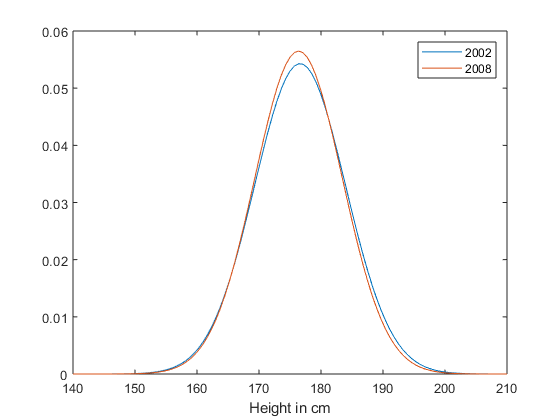

height02 = hw02.Height;
height08 = hw08.Height;

hfit02 = fitdist(height02,'Normal');
hfit08 = fitdist(height08,'Normal');

x = linspace(140,210,101);
plot(x,pdf(hfit02,x),x,pdf(hfit08,x))
xlabel('Height in cm')
legend('2002','2008')

## 3.

Calculate the mean heights for both years, and the difference between them. Perform an appropriate hypothesis test to determine if the difference is statistically significant.

avgheight02 = mean(hfit02)

avgheight02 = 176.6260

avgheight08 = mean(hfit08)

avgheight08 = 176.3805


[h,p] = ttest2(height02,height08)

h = 0

p = 0.3798

% At the 5% level of significance the difference of the average heights is not statistically significant

## 4.

Perform the same analysis for weight, except with a lognormal distribution fit. To test the significance of the difference, you can transform the data to be normal, and then perform a hypothesis test. Note that, if weight is lognormally distributed, then the logarithm of weight will be normally distributed.

**Remark:** For a lognnormal distribution `lnd`, the exponential of the parameter `mu` is the logarithm of its median:

`lnd.mu = log(lnd.median)`

Hence, we are basically testing for equal medians of the two lognormal distributions.

weight02 = hw02.Weight;
weight08 = hw08.Weight;

wfit02 = fitdist(weight02,'Lognormal');
wfit08 = fitdist(weight08,'Lognormal')

wfit08 =   LognormalDistribution

  Lognormal distribution
       mu =  4.45674   [4.44521, 4.46828]
    sigma = 0.214593   [0.206742, 0.223068]


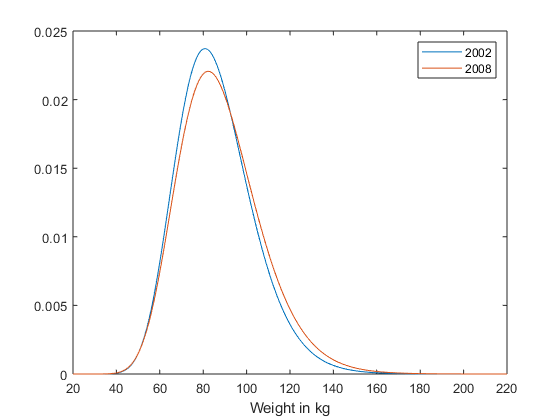


x = linspace(20,220,201);
plot(x,pdf(wfit02,x),x,pdf(wfit08,x))
xlabel('Weight in kg')
legend('2002','2008')

avgweight02 = nanmean(weight02)

avgweight02 = 86.0484

avgweight08 = nanmean(weight08)

avgweight08 = 88.2483


[h,p] = ttest2(log(weight02),log(weight08))

h = 1

p = 0.0048

% At the 5% level of significance there is a difference in the median weights

## 5.

Perform the analysis again for BMI. Use a nonparametric distribution fit and compare the medians. Again, choose an appropriate hypothesis test to determine if the difference is significant.

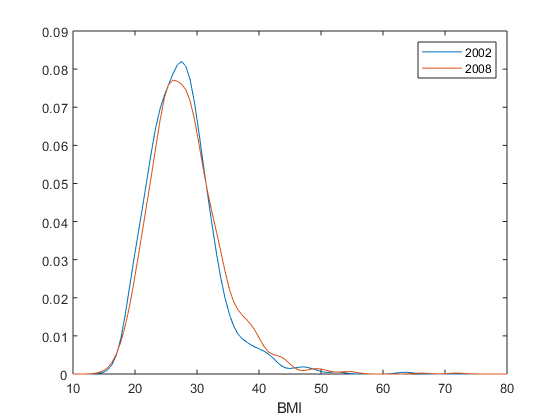

bmi02 = hw02.BMI;
bmi08 = hw08.BMI;

bmifit02 = fitdist(bmi02,'Kernel');
bmifit08 = fitdist(bmi08,'Kernel');

x = linspace(10,80,101);
plot(x,pdf(bmifit02,x),x,pdf(bmifit08,x))
xlabel('BMI')
legend('2002','2008')

medbmi02 = nanmedian(bmi02)

medbmi02 = 27.1400

medbmi08 = nanmedian(bmi08)

medbmi08 = 27.5650


[p,h] = ranksum(bmi02,bmi08)

p = 0.0021

h = logical
   1

% At the 5% level of significance there is a difference in the bmi medians